# Test cuadraturi gaussiene

## Problema 1 : Gauss-Legendre

Aproximați 


$$\displaystyle\int_{1}^{\pi}\frac{\ln x}{x^2-2x+2}\,\mathrm{d}x$$


cu 8 zecimale exacte folosind o cuadratură Gauss-Legendre.

f=@(x) log(x)./(x.^2-2*x+2);
n0=5; a=1; b=pi;
tol=1e-8;
format long
vi(1)=Gauss_Legendre_ab(f,n0,a,b); k=1;
for n=n0+1:10*n0
    k=k+1;
    vi(k)=Gauss_Legendre_ab(f,n,a,b);
    if abs(vi(k)-vi(k-1))<tol
        fprintf('vi(%d)=%12.10f\n',n,vi(k))
        break
    end 
end

vi(11)=0.5849428068


integral(f,a,b,'AbsTol',1e-8)

ans =    0.584942806931288


## Problema 2 : Gauss-Cebîșev #1

Determinați o formulă de cuadratură de forma


$$\displaystyle\int_{-1}^1\frac{f(x)}{\sqrt{1-x^2}}\,\mathrm{d}x=\sum_{k=1}^{10}A_kf(x_k)+R(f)$$


care să aibă grad maxim de exactitate. Să se aplice formula pentru a calcula

$\displaystyle\int_{-1}^1\frac{xe^{-x^2}}{\sqrt{1-x^2}}\,\mathrm{d}x$. Verificare.

clear
syms t f(t)
R=diff(f(t),t,20)/factorial(20)*int((1-t^2)^(-sym(1)/sym(2))*chebyshevT(10,t)^2,t,-1,1)

$$R = \frac{\pi \,\frac{\partial^{20}}{\partial t^{20}}f\left(t\right)}{4865804016353280000}$$

f=@(x) x.*exp(-x.^2)

f = function_handle with value:
    @(x)x.*exp(-x.^2)


[gn,gc]=Gauss_Cheb1(10);
vi=vquad(gn,gc,f)

vi =      8.326672684688674e-17


Valoarea exactă a integralei este 0.

## Problema 3 : Gauss-Cebîșev #2

Determinați o formulă de cuadratură de forma


$$\displaystyle\int_{-1}^1\sqrt{1-x^2}f(x)\,\mathrm{d}x=\sum_{k=1}^{10}A_kf(x_k)+R(f)$$


care să aibă grad maxim de exactitate. Să se aplice formula pentru a calcula

$\displaystyle\int_{-1}^1\sqrt{1-x^2}e^{-x^2}\,\mathrm{d}x$. Cât este eroarea?

D10=diff(exp(-t^2),t,20)

$$D10 = 670442572800\,{\mathrm{e}}^{-t^{2}}-13408851456000\,t^{2}\,{\mathrm{e}}^{-t^{2}}+40226554368000\,t^{4}\,{\mathrm{e}}^{-t^{2}}-42908324659200\,t^{6}\,{\mathrm{e}}^{-t^{2}}+21454162329600\,t^{8}\,{\mathrm{e}}^{-t^{2}}-5721109954560\,t^{10}\,{\mathrm{e}}^{-t^{2}}+866834841600\,t^{12}\,{\mathrm{e}}^{-t^{2}}-76205260800\,t^{14}\,{\mathrm{e}}^{-t^{2}}+3810263040\,t^{16}\,{\mathrm{e}}^{-t^{2}}-99614720\,t^{18}\,{\mathrm{e}}^{-t^{2}}+1048576\,t^{20}\,{\mathrm{e}}^{-t^{2}}$$

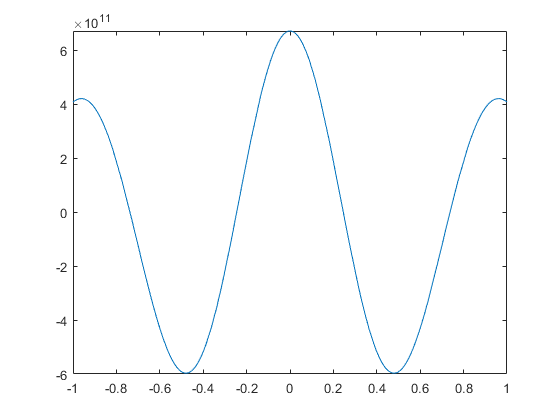

fplot(D10,[-1,1])

Md=subs(D10,t,sym(0))

$$Md = 670442572800$$

R=1/factorial(20)*int(sqrt(1-t^2)*chebyshevU(10,t)^2,t,-1,1)*Md

$$R = \frac{5589288360794662244495775\,\pi }{40564819207303340847894502572032}$$

vpa(R)

$$ans = 0.00000043286935813351427847312309828726$$

f=@(x) exp(-x.^2);
[gn,gc]=Gauss_Cheb1(10);
vi=vquad(gn,gc,f)

vi =    2.026438066948348


## Problema 4 : Gauss-Laguerre

Un vârf de tensiune într-un circuit este provocat de un curent


$$i(t) = i_0e^{-\frac{t}{t_0}} \sin\left(2\frac{t}{t_0}\right)$$


printr-un rezistor. Energia $E$ disipată de rezistor este


$$E=\displaystyle\int_{0}^{\infty}Ri^2(t)\,\mathrm{d}t$$


Determinați E cunoscând $i_0 = 100A$, $R = 0.5\Omega$ și $t_0 = 0.01s$.

Integrala de calculat se scrie


$$E={\textrm{Ri}}_0^2 \int_0^{\infty } e^{-\frac{2t}{t_0 }} \sin^2 \left(\frac{2t}{t_0 }\right)\textrm{dt}={\textrm{Ri}}_0^2 \frac{t_0 }{2}\int_0^{\infty } e^{-u} \sin^2 \left(u\right)\textrm{du}$$


f=@(u) sin(u).^2;
n=20;
[nodes,coeffs]=Gauss_Laguerre(n,0)

nodes =    0.070539889691990
   0.372126818001612
   0.916582102483274
   1.707306531028345
   2.749199255309430
   4.048925313850883
   5.615174970861618
   7.459017453671063
   9.594392869581092
  12.038802546964316


coeffs =    0.168746801851115   0.291254362006067   0.266686102867001   0.166002453269507   0.074826064668792   0.024964417309283   0.006202550844572   0.001144962386477   0.000155741773028   0.000015401440865   0.000001086486367   0.000000053301209   0.000000001757981   0.000000000037255   0.000000000000477   0.000000000000003   0.000000000000000   0.000000000000000   0.000000000000000   0.000000000000000


i0=100; R=0.5; t0=0.01;
E=R*i0^2*t0/2*vquad(nodes,coeffs,f)

E =   10.000037265978543


vpa(R*i0^2*t0/2*int(exp(-t)*sin(t)^2,t,0,sym(Inf)))

$$ans = 10.0$$

R=vpa(1/factorial(32)*int(exp(-t)*laguerreL(n,t)^2,t,sym(0),sym(inf))*sym(2147483648))

$$R = 0.0000000000000000000000000081612770020609395403676956342367$$

## Problema 5 : Gauss-Hermite

Determinați o formulă de cuadratură de forma

$\displaystyle\int_{-\infty}^\infty e^{-x^2}f(x)\,\mathrm{d}x=\sum_{k=1}^n A_kf(x_k)+R(f)$.

care să aibă grad maxim de exactitate. Aplicați formula pentru a calcula

$\displaystyle\int_{-\infty}^\infty e^{-x^2}\sin x\,\mathrm{d}x$ și $\displaystyle\int_{-\infty}^\infty e^{-x^2}\cos x\,\mathrm{d}x$

cu o precizie dată.

err=1e-8;
for n = 5:20
    R=vpa(1/factorial(2*n)*int(exp(-t^2)*hermiteH(n,t)^2,t,sym(-Inf),sym(Inf)));
    if R<err
        R,n, break;
    end  
end

$$R = 0.0000000027071561636475606663458403563538$$

n =     10


[no,co]=Gauss_Hermite(n);
v1=vquad(no,co,@sin)

v1 =     -2.165151738453552e-16


v2=vquad(no,co,@cos)

v2 =    1.380388447043140


ve=int(exp(-t^2)*cos(t),t,sym(-Inf),sym(Inf))

$$ve = \sqrt{\pi }\,{\mathrm{e}}^{-\frac{1}{4}}$$

double(ve)

ans =    1.380388447043143


## Problema 6 : Gauss-Jacobi

Aproximați $\displaystyle\int_0^{\frac{\pi}{2}}\frac{1}\sqrt{\sin x}\,\mathrm{d}x$ cu 9 zecimale exacte, folosind o cuadratură Gauss-Jacobi.

syms t u
err=1e-9;
ve=vpa(int(1/sqrt(sin(t)),t,sym(0),sym(pi)/sym(2)))

$$ve = 2.6220575542921198104648395898911$$

ved=double(ve);
II = int(1/sqrt(sin(t)),t,0,sym(pi)/sym(2),'Hold',true)

$$II = \int_{0}^{\frac{\pi }{2}}\frac{1}{\sqrt{\sin\left(t\right)}}\mathrm{d}t$$

changeIntegrationVariable(II,t,asin((u+1)/2))

$$ans = \int_{-1}^{1}\frac{1}{2\,\sqrt{\frac{1}{2}+\frac{u}{2}}\,\sqrt{1-{\left(\frac{1}{2}+\frac{u}{2}\right)}^{2}}}\mathrm{d}u$$

f=@(x) sqrt(2)./sqrt(x+3);
n0=10; b=-1/2; a=-1/2;
[gn,gc]=Gauss_Jacobimodificat(n0,a,b);
vi(1)=vquad(gn,gc,f); k=1;

for n=n0+1:10*n0
    k=k+1;
    [gn,gc]=Gauss_Jacobimodificat(n,a,b);
    vi(k)=vquad(gn,gc,f);
    if (abs(vi(k)-ved)<err) || n>1000
        fprintf('vi(%d)=%11.9f\n',n,vi(k));
        break
    end
end

vi(11)=2.622057554


n,vi(k)

n =     11


ans =    2.622057554292121


## Problema 7

Aproximați integralele  


$$\textrm{Ic}=\int_0^1 \frac{\cos \left(x\right)}{\sqrt{x}}\textrm{dx},\textrm{Is}=\int_0^1 \frac{\sin \left(x\right)}{\sqrt{x}}\textrm{dx}$$


cu o precizie dată:

- utilizând o cuadratură adaptivă;

- utilizând o cuadratură Gauss-Legendre, după ce s-a efectuat schimbarea de variabilă $x = t^2$;

- utilizând o cuadratură Gauss-Jacobi.

Cu schimbarea de variabilă $x = t^2$ integralele din enunț devin


$$\textrm{Ic}=\int_0^1 \frac{\cos \left(x\right)}{\sqrt{x}}\textrm{dx}=\int_0^1 2\cos \left(t^2 \right)\textrm{dt}=\int_{-1}^1 \cos \left(t^2 \right)\textrm{dt}$$



$$\textrm{Is}=\int_0^1 \frac{\sin \left(x\right)}{\sqrt{x}}\textrm{dx}=\int_0^1 2\sin \left(t^2 \right)\textrm{dt}=\int_{-1}^1 \sin \left(t^2 \right)\textrm{dt}$$


Dacă efectuăm schimbarea de variabilă $x = \frac{t+1}{2}$ obținem


$$\textrm{Ic}=\int_0^1 \frac{\cos \left(x\right)}{\sqrt{x}}\textrm{dx}=\frac{\sqrt{2}}{2}\int_{-1}^1 {\left(t+1\right)}^{-\frac{1}{2}} \cos \frac{t+1}{2}\textrm{dt}$$



$$\textrm{Is}=\int_0^1 \frac{\sin \left(x\right)}{\sqrt{x}}\textrm{dx}=$$

$$\frac{\sqrt{2}}{2}\int_{-1}^1 {\left(t+1\right)}^{-\frac{1}{2}} \sin \frac{t+1}{2}\textrm{dt}$$


Ponderea este $w(t)=(t+1)^{-\frac{1}{2}}=(1-t)^0(1+t)^{-1/2}$, deci $\alpha=0$, $\beta=-1/2$.

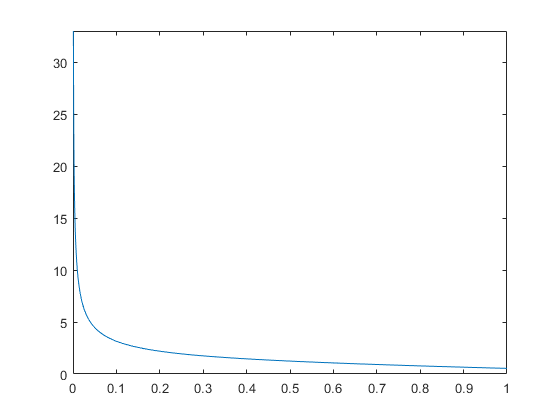

f1=@(x) cos(x)./sqrt(x);
f2=@(x) sin(x)./sqrt(x);
fplot(f1,[0,1]); 

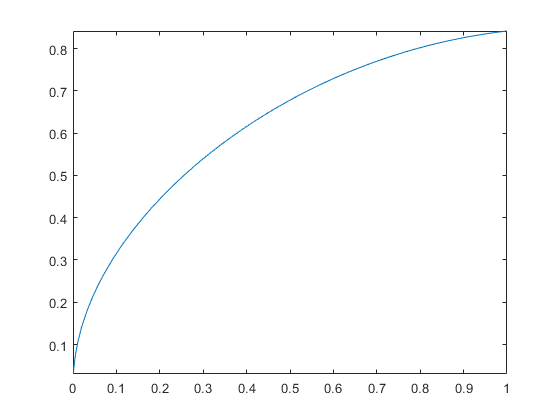

fplot(f2,[0,1]); 


f1a=@(t) 2*cos(t.^2);
f2a=@(t) 2*sin(t.^2);
f1b=@(t) 1/sqrt(2)*cos((t+1)/2);
f2b=@(t) 1/sqrt(2)*sin((t+1)/2);
[I1,n1]=quadl(f1,0,1,1e-8)

I1 =    1.809048461548056


n1 =    799


[I2,n2]=quadl(f2,0,1,1e-8)

I2 =    0.620536602409682


n2 =    169


a=0; b=1;
n=150;
[g_nodes,g_coeff]=Gauss_Legendre(n);
I1a=(b-a)/2*g_coeff*f1a((b-a)/2*g_nodes+(b+a)/2)

I1a =    1.809048475800545


I2a=(b-a)/2*g_coeff*f2a((b-a)/2*g_nodes+(b+a)/2)

I2a =    0.620536603446762


n=100;
[g_nodes,g_coeff]=Gauss_Jacobi(n,0,-1/2);
I1b=g_coeff*f1b(g_nodes)

I1b =    1.809048475800544


I2b=g_coeff*f2b(g_nodes)

I2b =    0.620536603446763


syms t Ic Is
Ic=vpa(int(cos(t)/sqrt(t),t,0,1))

$$Ic = 1.8090484758005441629495767336651$$

Is=vpa(int(sin(t)/sqrt(t),t,0,1))

$$Is = 0.62053660344676220361630484633079$$

disp('adaptive')

adaptive


abs(I1-double(Ic))

ans =      1.425248807862545e-08


abs(I2-double(Is))

ans =      1.037080088472919e-09


disp('erori legendre')

erori legendre


abs(I1a-double(Ic))

ans =      4.440892098500626e-16


abs(I2a-double(Is))

ans =      1.110223024625157e-16


disp('erori Jacobi')

erori Jacobi


abs(I1b-double(Ic))

ans =      0


abs(I2b-double(Is))

ans =      3.330669073875470e-16
